clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_colon_9_26.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

arm = 'psm3_fena';


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
    

%       joint_path = ['../../../Downloads/trial_pipeline_1', '/joints/'];
%       jacobian_path = ['../../../Downloads/trial_pipeline_1', '/jacobian/'];
%       torque_path = ['../../../Downloads/trial_pipeline_1', '/TO_free_comp_model_pred.csv'];
%       corr_tq_path = ['../../../Downloads/trial_pipeline_1', '/filtered_corrected_torque_prediction.csv'];

      
      joint_path = ['../../../Downloads/test_contact_10', '/joints/'];
      jacobian_path = ['../../../Downloads/test_contact_10', '/jacobian/'];
      torque_path = ['../../../Downloads/test_contact_10', '/TO_free_comp_model_pred.csv'];
      corr_tq_path = ['../../../Downloads/test_contact_10', '/filtered_corrected_torque_prediction.csv'];

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian.csv']);
torque_data = readmatrix(torque_path);
corr_tq = readmatrix(corr_tq_path);

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =     0.0000   -0.0000   -0.3972   -0.0000   -0.1206   -0.0262
    0.0000   -0.0000    0.2275   -0.0000    0.0162   -0.1235
    0.0000   -0.0000   -0.8891    0.0000    0.0580   -0.0199
   -0.0000   -0.9130         0   -0.3972   -0.2046    0.9761
   -1.0000   -0.0000         0    0.2275   -0.9664   -0.2134
    0.0000    0.4079         0   -0.8891   -0.1559    0.0420



corr_pred_torque = corr_tq(:,2:7).';
fs_pred_torque = torque_data(1:length(corr_pred_torque),1:6).';

% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(corr_pred_torque),14:19).';
jacobian = jacobian(:,:,1:length(corr_pred_torque));

fs_diff = measured_torque  - fs_pred_torque + corr_pred_torque;
fs_diff_wo_corr = measured_torque ;
fs_force = zeros(6,length(fs_pred_torque));

angle = pi/2;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]

Ra =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071]

Rz =    -1.0000         0         0
         0   -0.7071   -0.7071
         0   -0.7071    0.7071


% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz)

ans = 1.0000

another_angle = -1/2*pi;
rotation = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1]

rotation =     0.0000    1.0000         0
   -1.0000    0.0000         0
         0         0    1.0000



for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(jacobian(:,:,i).') * (fs_diff(:,i));
    fs_force_wo_corr(:,i) = inv(jacobian(:,:,i).') * (fs_diff_wo_corr(:,i));
    fs_force(1:3, i) = rotation * fs_force(1:3, i);
    fs_force_wo_corr(1:3, i) = rotation * fs_force_wo_corr(1:3, i);
end

fs_force = fs_force.';
fs_force_wo_corr = fs_force_wo_corr.';


real_force_path = ['../../../Downloads/test_contact_10/', 'sensor/'];
% real_force_path = ['dvrk-si-3-15/csv_si/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);



windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force_unfilt = fs_force;

% fs_force = filter(b,a,fs_force);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));
loss_taux = mean(sqrt(mean( (fs_force(:,4) - real_force(:,4)).^2 )));
loss_tauy = mean(sqrt(mean( (fs_force(:,5) - real_force(:,5)).^2 )));
loss_tauz = mean(sqrt(mean( (fs_force(:,6) - real_force(:,6)).^2 )));

loss_x_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,1) - real_force(:,1)).^2 )));
loss_y_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,2) - real_force(:,2)).^2 )));
loss_z_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,3) - real_force(:,3)).^2 )));

[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix)

boundX = 18.3640

[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy)

boundY = 6.7053

[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz)

boundZ = 17.4750

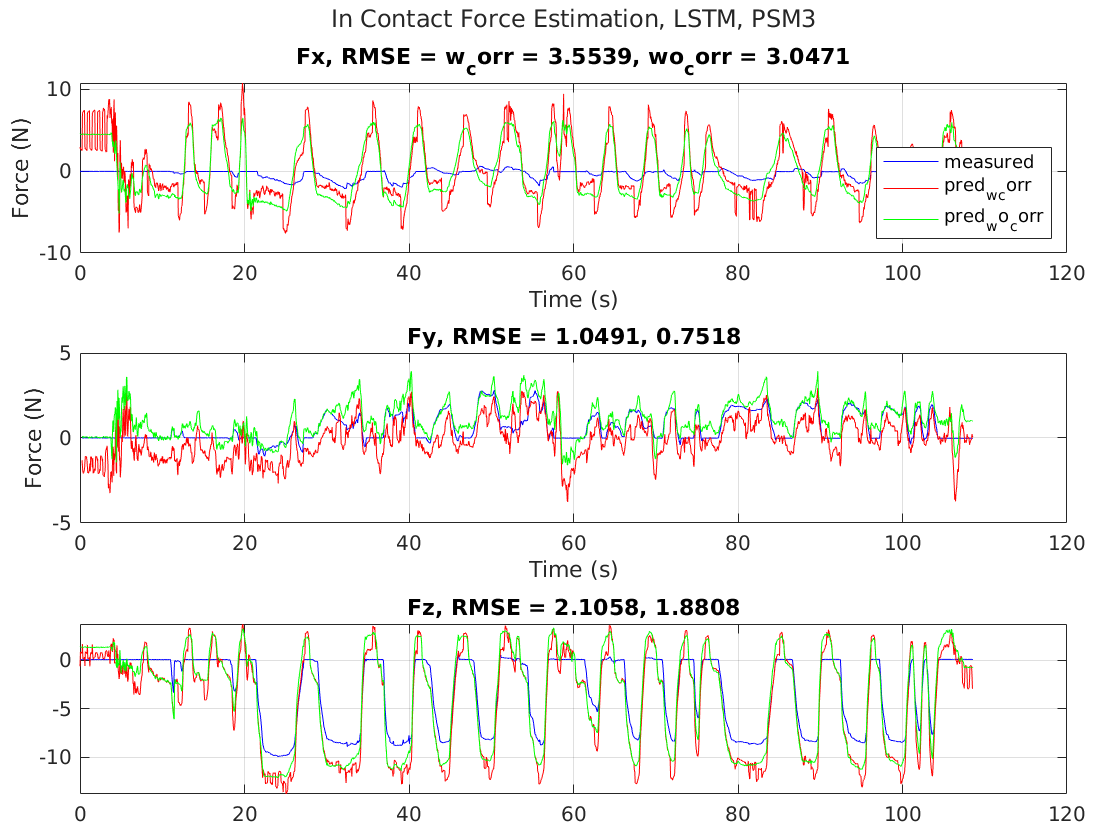


figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('In Contact Force Estimation, LSTM, PSM3'))



nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx, RMSE = w_corr = %.4f, wo_corr = %.4f', loss_x, loss_x_wo_corr))
plot(joint_data(1:length(real_force)), fs_force(:,1), 'r')
plot(joint_data(1:length(real_force)), fs_force_wo_corr(:,1), 'g')
xlabel('Time (s)')
ylabel('Force (N)')
grid on

legend('measured', 'pred_w_corr', 'pred_wo_corr','Location', 'southeast')

hold off

nexttile
plot(joint_data(6:length(real_force)), real_force(6:length(real_force),2), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f, %.4f', loss_y, loss_y_wo_corr))
plot(joint_data(6:length(real_force)), fs_force(6:length(real_force),2), 'r')
plot(joint_data(6:length(real_force)), fs_force_wo_corr(6:length(real_force),2), 'g')
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,3), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f, %.4f', loss_z,  loss_z_wo_corr))
plot(joint_data(1:length(real_force)), fs_force(:,3), 'r')
plot(joint_data(1:length(real_force)), fs_force_wo_corr(:,3), 'g')
grid on


hold off